format longg
CP = py.importlib.import_module("CoolProp.CoolProp");

zeta_ind = 0.2;
zeta_boj_90 = 0.30;
zeta_boj_135 = zeta_boj_90 * 1.5;
zeta_boj_180 = zeta_boj_90 * 2;
zeta_buffer = 1 + 0.25;
zeta_flow = 1;
zeta_filter = 3;
zeta_skue = zeta_buffer;
% zeta_epv = 69


zeta_total = zeta_ind + 5*zeta_boj_90 + 3*zeta_boj_135 + zeta_boj_180...
    + zeta_buffer + zeta_flow + zeta_filter + zeta_skue %+ zeta_epv


# **Område 3**

**For væske**

L = 1.95 %1.95; %m
t = 0.00080; %m
d = 0.00794 - 2*t %m
d_i = 0.008 - 2*0.0002 %m diameteren ud af kondensatoren


c_foer_kond = 5.24 % m/s
c_efter_kond = 0.1495 % m/s

c_i = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

% c * d^2 = d_i^2 * c_i %countinuitetsligningen
c = d_i^2 * c_i / d^2

rho_fluid = 1186.61436781861; %kg/m^3 




nu = CP.PropsSI('V', 'H', 242310, 'P', 886810, 'R134a') % |not_imposed %m^2/s  
Re = c * d / nu 

% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_enkelt = zeta_total * (rho_fluid * c^2)/ 2


**For gas**

c = 2.26638867101572; %m/s    
rho_vape = 31.2106794247976; %kg/m^3 



L = 6.7 %1.95%1.95 %m
t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

nu = CP.PropsSI('V', 'H', 390410, 'P', 132700, 'R134a') % |not_imposed %m^2/s  
Re = c * d / nu 

% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

Delta_p_ror = lambda * L * c^2 * rho_vape / (d * 2)

% Delta_p = zeta_total * (rho * c^2)/ 2


# Fordamperen

rho1 = CP.PropsSI('D', 'Q', 0, 'P', 886810, 'R134a')%1186.61436781861; %kg/m^3 
c1 = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

c_for_ford = 8.41 %m/s
c_uden_ford = 26.57 %m/s

d1 = 0.008 - 2*0.0002
d2 = 0.00952 - 2*t
% c1 = 2.26638867101572; %m/s     
% rho = CP.PropsSI('D', 'H', 242310, 'P', 132700, 'R134a')%1186.61436781861; %kg/m^3 
rho_for = CP.PropsSI('D', 'T', 273.15 -20, 'P', 132700, 'R134a')%1186.61436781861; %kg/m^3 

c2 = c1 * rho1 * d1^2 / (d2^2 * rho_for )

L = 6.7 %1.95%1.95 %m
t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

nu = CP.PropsSI('V', 'T', 273.15 -20, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d
% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

% lambda = 64/Re  % <-----------
lambda = 0.035
Re = c2 * d2 / nu

Delta_p_ror = lambda * L * c2^2 * rho_for / (d2 * 2)

% Delta_p = zeta_total * (rho * c^2)/ 2

# For Kondensatoren

**For væske**

L = 19.71 %1.95; %m
t = 0.0002; %m
d = 0.008 - 2*t %m diameteren ud af kondensatoren

c_fluid = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren


c_foer_kond = 5.24 % m/s
c_efter_kond = 0.1495 % m/s


rho_fluid = 1186.61436781861; %kg/m^3 




nu = CP.PropsSI('V', 'H', 390410, 'P', 886810, 'R134a') % |not_imposed %m^2/s  
Re = c * d / nu 

% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

Delta_p_ror = lambda * L * c_fluid^2 * rho_fluid / (d * 2)


**For gas**

c_vape = 2.26638867101572; %m/s    
rho_vape = 31.2106794247976; %kg/m^3 


L = 19.71 %1.95%1.95 %m
t = 0.0002; %m
d = 0.008 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

nu = CP.PropsSI('V', 'H',  489800, 'P', 886810, 'R134a') % |not_imposed %m^2/s  
Re = c * d / nu 

% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

Delta_p_ror = lambda * L * c_vape^2 * rho_vape / (d * 2)


enektl modstande


zeta_boj_90 = 0.30;

zeta_boj_180 = zeta_boj_90 * 2;



zeta_total = zeta_boj_180 * 56

Delta_p = zeta_total * (rho_fluid * c_fluid^2)/ 2
Delta_p = zeta_total * (rho_vape * c_vape^2)/ 2

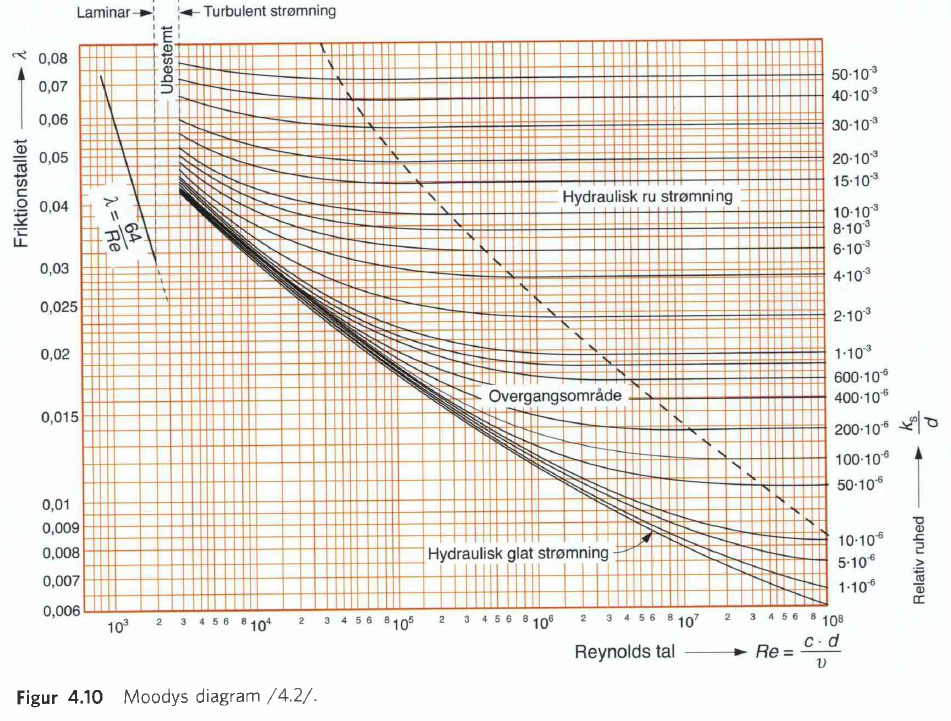

Video til coolprop

[https://www.youtube.com/watch?v=XvR10Fjph7U](https://www.youtube.com/watch?v=XvR10Fjph7U) 

For coolprop

[https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png](https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png)